# Working with [Physionet](http://physionet.org) ECG database.

We have used in our work two databases - MIT-BIH Arrythmia database and QT-Database accessed via Physionet.

To this end we use [wfdb toolbox](https://archive.physionet.org/physiotools/wfdb.shtml) provided by Physionet, the instructions to install in matlab are [here](https://archive.physionet.org/physiotools/matlab/wfdb-app-matlab/).

We now show two examples to illustrate the process of obtaining data. First install the toolbox and then change directory to the folder where wfdb is installed.

- [MITDB](https://physionet.org/content/mitdb/1.0.0/) 

[sig, Fs, tm] = rdsamp('mitdb/103', 1);

Here the signal is stored in sig, sampling frequency in Fs and the timestamp in tm. Here we are importing record no. 103. To get the annotations, use:

[record, ann] = rdann('mitdb/103','atr');

Here the indices of annotations are stored in record and the corresponding annotations are stored in ann. The key to annotations can be found [here](https://archive.physionet.org/physiobank/annotations.shtml).

Let us now try to visualize the signal for first 20 seconds

duration=20;
record_temp = record(find(record<duration*360));
ann_temp = ann(1:size(record_temp,1));
close 
plot(tm(1:360*duration),sig(1:360*duration));

We can now put annotations on it. Recall from the key that 'N' refers to normal beat.

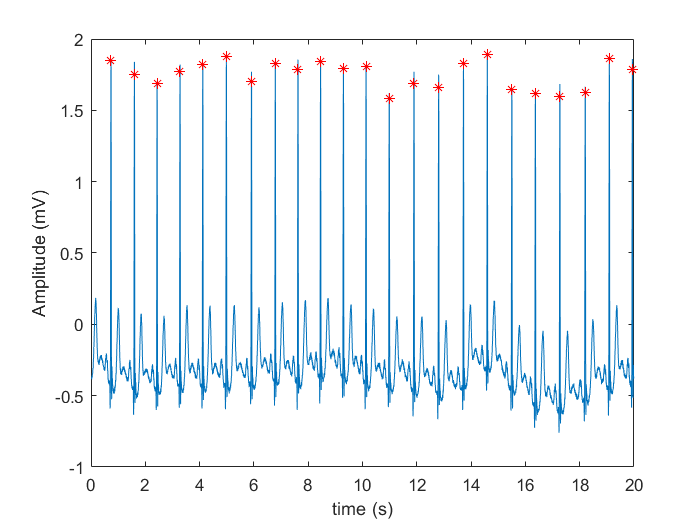

hold on;
plot(tm(record_temp(find(ann_temp=='N'))),sig(record_temp(find(ann_temp=='N'))),'r*')
xlabel('time (s)')
ylabel('Amplitude (mV)')

2. [QTDB](https://physionet.org/content/qtdb/1.0.0/)

[sig, Fs, tm] = rdsamp('qtdb/sel123', 1);

Here the signal is stored in sig, sampling frequency in Fs (250Hz) and the timestamp in tm. Here we are importing record no. 102. To get the annotations,  there are several files which can obtain, a detailed list is available on qtdb mainpage, here we import T and P wave dilineations using 'pu0' attribution

[record, ann] = rdann('qtdb/sel123','pu0');

Here the indices of annotations are stored in record and the corresponding annotations are stored in ann. The key to annotations can be found [here](https://archive.physionet.org/physiobank/annotations.shtml).

Let us now try to visualize the signal for first 20 seconds

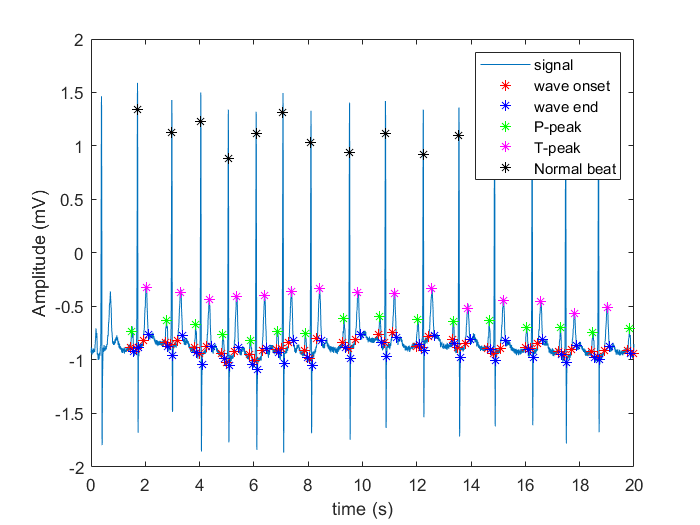

duration=20;
record_temp = record(find(record<duration*250));
ann_temp = ann(1:size(record_temp,1));
close 
plot(tm(1:250*duration),sig(1:250*duration),tm(record_temp(find(ann_temp=='('))),sig(record(find(ann_temp=='('))),'r*');
hold on
plot(tm(record_temp(find(ann_temp==')'))),sig(record_temp(find(ann_temp==')'))),'b*');
plot(tm(record_temp(find(ann_temp=='p'))),sig(record_temp(find(ann_temp=='p'))),'g*');
plot(tm(record_temp(find(ann_temp=='t'))),sig(record_temp(find(ann_temp=='t'))),'m*');
plot(tm(record_temp(find(ann_temp=='N'))),sig(record_temp(find(ann_temp=='N'))),'k*');
legend('signal','wave onset','wave end','P-peak','T-peak','Normal beat')
xlabel('time (s)')
ylabel('Amplitude (mV)')

Physionet has a wealth  of accessible databases, the following command shows the list of databases and the file name prefix and the URLs

physionetdb

adfecgdb
	Description: Abdominal and Direct Fetal ECG Database
	URL: http://physionet.org/physiobank/database/pbi/adfecgdb
aftdb
	Description: AF Termination Challenge Database
	URL: http://physionet.org/physiobank/database/pbi/aftdb
ahadb
	Description: AHA Database [sample excluded record]
	URL: http://physionet.org/physiobank/database/pbi/ahadb
aami-ec13
	Description: ANSI/AAMI EC13 Test Waveforms
	URL: http://physionet.org/physiobank/database/pbi/aami-ec13
apnea-ecg
	Description: Apnea-ECG Database
	URL: http://physionet.org/physiobank/database/pbi/apnea-ecg
chfdb
	Description: BIDMC Congestive Heart Failure Database
	URL: http://physionet.org/physiobank/database/pbi/chfdb
bidmc
	Description: BIDMC PPG and Respiration Dataset
	URL: http://physionet.org/physiobank/database/pbi/bidmc
bpssrat
	Description: Blood Pressure in Salt-Sensitive Dahl Rats
	URL: http://physionet.org/physiobank/database/pbi/bpssrat
capslpdb
	Description: CAP Sleep Database
	URL: http://physionet.org/physiobank/